# Create a Table from a MATLAB Table

This example creates a DOM table from a MATLAB table that has row names. The example generates two reports that include the DOM table. In the first report, the row names column of the table does not have a label. In the second report, the row names column has a label.

Create a MATLAB table that shows the age, weight, and height of patients. Use the `RowNames` option to identify each row by the last name of the patient. 

LastName = {'Sanchez';'Johnson';'Lee';'Diaz';'Brown'};
Age = [38;43;38;40;49];
Weight = [176;163;131;133;119];
Height = [71;69;64;67;64];
mltable = table(Age,Weight,Height,'RowNames',LastName)

The MATLAB table has five rows and three columns. The row names are not part of the table. They are stored in a property of the table. 

Create an `mlreportgen.dom.MATLABTable` object from the `MATLAB` table. 

import mlreportgen.dom.*
mltableObj = MATLABTable(mltable);

Create a document and append the `MATLABTable` object to the document. Close and view the document.

d = Document('MyMATLABTable1','docx');
append(d,mltableObj);
close(d);
rptview(d);

Here is the table in the generated report:

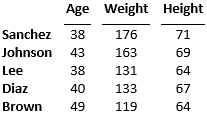

The DOM table is a formal table, which has a header and a body. The table body has five rows and four columns. The first column consists of the MATLAB table row names. 

Generate the report again, this time with a label for the column of row names. To specify the label, replace the empty text in the first entry of the table header row with the label text. To draw a line under the label, set the `RowNamesRule` property of the `MATLABTable` object to `true`.

LastName = {'Sanchez';'Johnson';'Lee';'Diaz';'Brown'};
Age = [38;43;38;40;49];
Weight = [176;163;131;133;119];
Height = [71;69;64;67;64];
mltable = table(Age,Weight,Height,'RowNames',LastName);
import mlreportgen.dom.*
mltableObj = MATLABTable(mltable);
th = mltableObj.Header;
thentry11 = entry(th,1,1);
thentry11.Children(1).Children(1).Content = 'Names';
mltableObj.RowNamesRule = true;
d = Document('MyMATLABTable2','docx');
append(d,mltableObj);
close(d);
rptview(d);

Here is the table in the generated report:

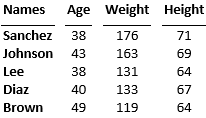

*Copyright 2020 The MathWorks, Inc.*